# FF_OPTIM_BISEC_SAVEZRONE Derivative Bisection

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_optim_bisec_savezrone**](https://github.com/FanWangEcon//MEconTools/blob/master/MEconTools/optim/ff_optim_bisec_savezrone.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This functions solves for optimal savings/borrowing level given an anonymous function that provides the derivative of a intertemporal savings problem. The function is vectorized in the sense of solving over a grid of state-space elements that are embeded in the anonymous function.

## Test FF_DISC_RAND_VAR_MASS2COVCOR Defaults

Call the function with defaults, this solves concurrently for many state-space points' optimization problems:

BISECT ENDsavings bisectioniteration=11


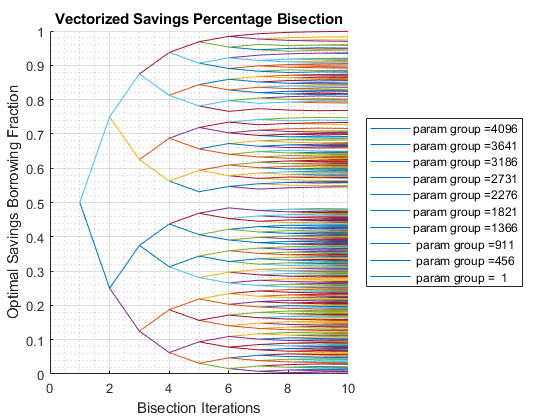

ff_optim_bisec_savezrone();

## Test FF_DISC_RAND_VAR_MASS2COVCOR Six Individual States

Solve the two period intertemporal optimization problem with only 6 individual states:

BISECT ENDsavings bisectioniteration=11


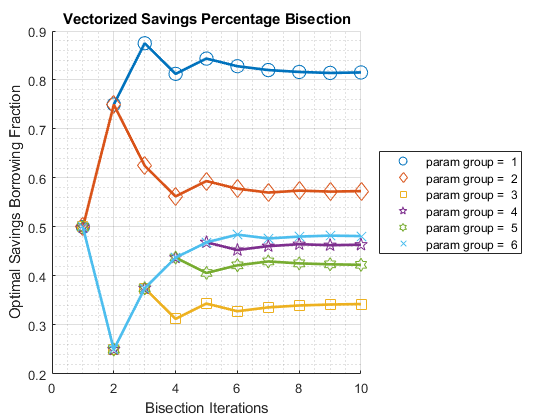

% Generate the state-space and function
ar_z1 = [1,1,2,2,3,3]';
ar_z2 = [3,3,2,2,1,1]';
ar_r = 1.10 + zeros(size(ar_z1));
ar_beta = [0.80, 0.95, 0.80, 0.95, 0.80, 0.95]';
mt_fc_inputs = [ar_z1, ar_z2, ar_r, ar_beta];
% ffi_intertemporal_max is a function in ff_optim_bisec_savezrone for testing
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = true;
ff_optim_bisec_savezrone(fc_deri_wth_uniroot, bl_verbose);

## Define Two Period Intertemporal FOC Log Utility No Shock

function [ar_deri_zero, ar_saveborr_level] = ffi_intertemporal_max(ar_saveborr_frac, z1, z2, r, beta)
    ar_saveborr_level = ar_saveborr_frac.*(z1-z2./(1+r));
    ar_deri_zero = 1./(ar_saveborr_level-z1) + (beta.*(r+1))./(z2 + ar_saveborr_level.*(r+1));
end